# DSZOB, cvičenie 5.

## **Zadanie:**

## **Úloha 1 Windowing**

Vygenerujte signál pre časový úsek 0-1s:

- Zložený signál obsahujúci 5 rôznych frekvencií a so vzorkovacou frekvenciou 44.1kHz. (vznikne aditívne so zvolenými násobnými koeficientami)

Vypočítajte Fourierovo spektrum (funkcia fft) zo selektovaného kratšieho časového úseku tohto signálu nasledujúcimi spôsobmi:

- Hammingovo okienko (windowing)

- Pravouhlé okienko (windowing)

Aký bol rozdiel vo výslednej Fourierovej transformácii pri použití Hammingovho a Pravouhlého okienka?

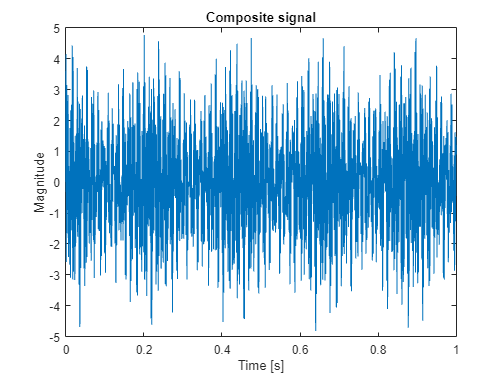

% Riesenie / Solution
fs = 44100;
time_axis = 0:1/fs:1;

composite = sin(time_axis * rand() * 600 * 2 * pi);
for j = 1:4 
    composite = composite + sin(time_axis * rand() * 600 * 2 * pi);
end
plot(time_axis, composite);
xlabel("Time [s]");
ylabel("Magnitude");
title("Composite signal");

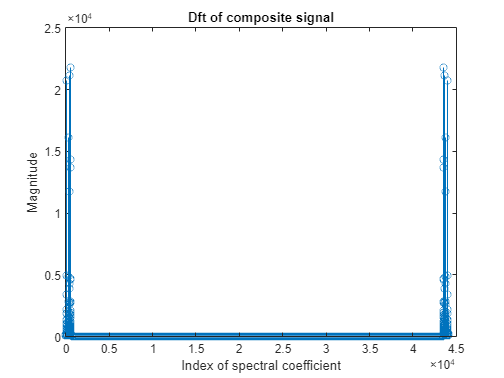

composite_dft = fft(composite);
stem(abs(composite_dft));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Dft of composite signal");

composite_rect = composite(1,1:1024) .* [zeros(1,300), ones(1, 424), zeros(1, 300)];
composite_hamming = composite(1,1:1024) .* hamming(1024).'; % Need to transpose hamming

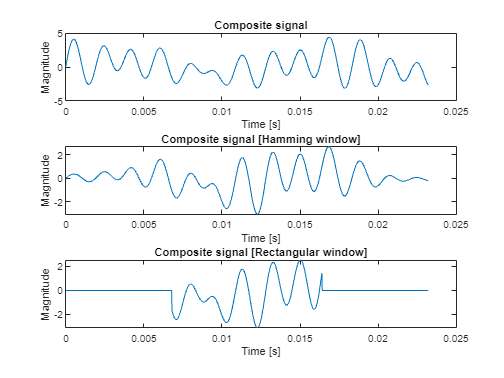

subplot(3,1,1);
plot(time_axis(1,1:1024), composite(1,1:1024));
xlabel("Time [s]");
ylabel("Magnitude");
title("Composite signal");

subplot(3,1,2);
plot(time_axis(1,1:1024), composite_hamming);
xlabel("Time [s]");
ylabel("Magnitude");
title("Composite signal [Hamming window]");

subplot(3,1,3);
plot(time_axis(1,1:1024), composite_rect);
xlabel("Time [s]");
ylabel("Magnitude");
title("Composite signal [Rectangular window]");

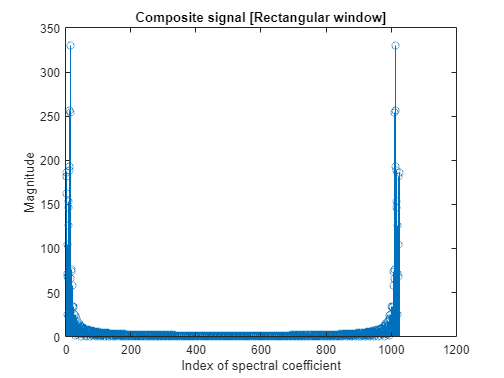

close all;
stem(abs(fft(composite_rect)));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Composite signal [Rectangular window]");

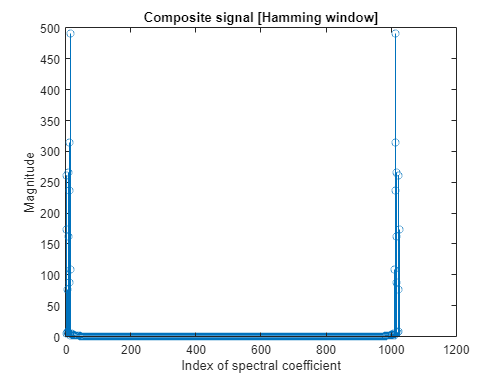

stem(abs(fft(composite_hamming)));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Composite signal [Hamming window]");

**Answer: **Hamming window reduces side-lobes, creates narrower peaks in our graphs

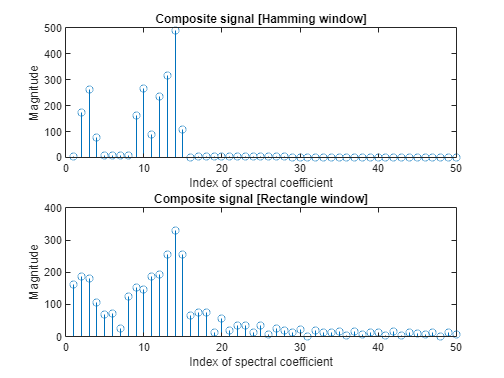

subplot(2,1,1);
stem(abs(fft(composite_hamming)));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Composite signal [Hamming window]");
xlim([0,50]);
subplot(2,1,2);
stem(abs(fft(composite_rect)));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Composite signal [Rectangle window]");
xlim([0,50]);

## **Úloha 2 **Redukcia dát v spektrálnej oblasti 

- Načítajte zvukovú stopu (napr. hudbu z dokumentového serveru) ako signál.

- Vizualizujte signál (celý aj detail okienka použitého v bode 3).

- Spočítajte kosínovú transformáciu (*dct*) aspoň pre jedno okienko a vizualizujte spektrum okienka (použite funkciu matlabu *stem*).

- Za pomoci cyklu *for* prejdite celým signálom tak, že vyberiete okienka bez prekryvu.

- Pre jednotlivé okienka vypočítajte *dct*, nastavte amplitúdy spektrálnych koeficientov, ktoré sú menšie ako zvolený prah (teda všetko, čo má menšiu amplitúdu ako zvolený prah) na hodnotu 0 a vypočítajte spätnú kosínovú transformáciu (*idct*). Takto získate nový, filtrovaný signál.

- Vizualizujte spektrum signálu pred a po filtrácií formou spektrogramu.

Vypočujte si výstupný, filtrovaný signál s rôznymi prahmi nulovania spektrálnych koeficientov. Porovnajte. Pri akej hodnote prahu došlo k značnému znehodnoteniu kvality zvukovej stopy?

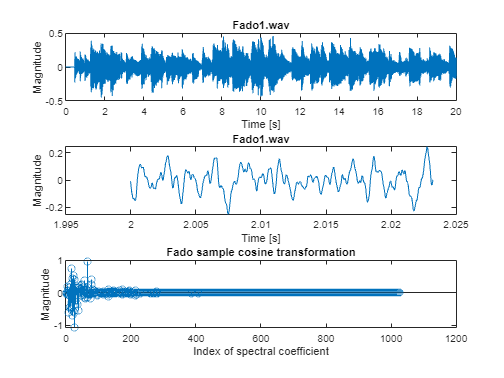

% Riesenie / Solution
close all;
fado = audioread("Asignments\Assignment_3\fado1.wav");
fado_info = audioinfo("Asignments\Assignment_3\fado1.wav");
fs = fado_info.SampleRate;
time_axis = 0:1/fs:fado_info.Duration;
time_axis(end) = [];    % Fix for rounding issue

fado_sample = fado(fs*2:fs*2+1024); % 1024 samples starting from second 2 

subplot(3,1,1);
plot(time_axis, fado);
title("Fado1.wav");
xlabel("Time [s]");
ylabel("Magnitude");
subplot(3,1,2);
plot(time_axis(fs*2:fs*2+1024), fado_sample);
title("Fado1.wav");
xlabel("Time [s]");
ylabel("Magnitude");
subplot(3,1,3);
stem(dct(fado_sample));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Fado sample cosine transformation");

**Answer: **In the creation of filtering function I wasnt sure whether to use absolute values of cosine transformation or not while comparing to set treshold, I'm assuming we shouldn't use absolute values but I tried both just in case.

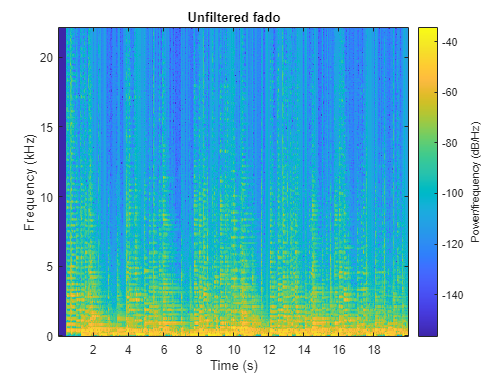

close all;
spectrogram(fado, hamming(512), 256, 512, fs, 'yaxis');
title("Unfiltered fado")

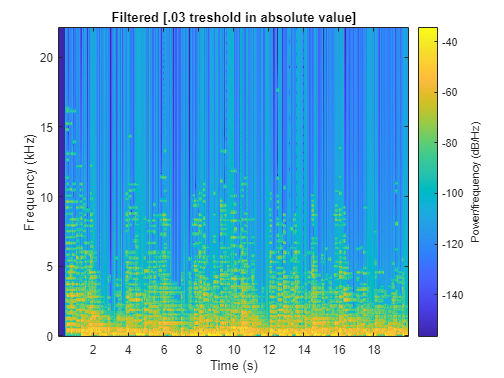

spectrogram(filter_signal_abs(fado, length(fado)/100, .03), hamming(512), 256, 512, fs, 'yaxis');
title("Filtered [.03 treshold in absolute value]");

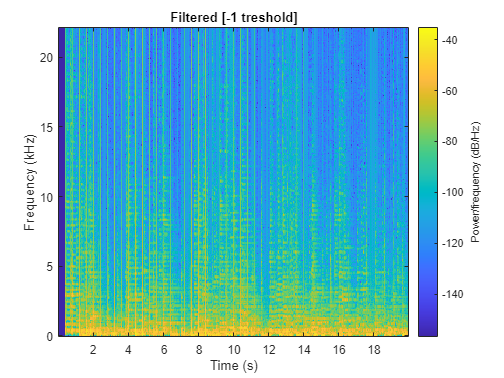

spectrogram(filter_signal(fado, length(fado)/100, -.1), hamming(512), 256, 512, fs, 'yaxis');
title("Filtered [-1 treshold]");

playblocking(audioplayer(fado, fs));

playblocking(audioplayer(filter_signal_abs(fado, length(fado)/100, .03), fs));

**Answer:** 0.3 as treshold using absolute values already creates a popping noise, which in my opinion already counts as significant deformation so I will choose this as an answer. 

playblocking(audioplayer(filter_signal(fado, length(fado)/100, -.1), fs));

At -2 the popping gets rather pronounced, bellow -0.1 the quality is already really bad

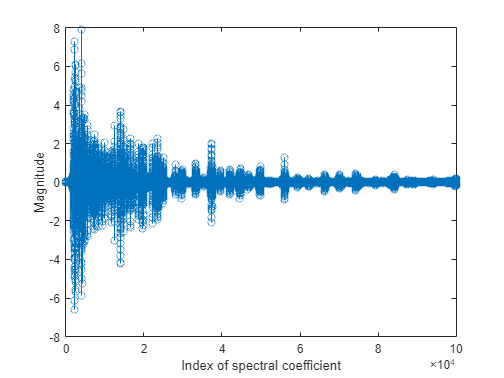

stem(dct(fado)) % Checking values of dct to get an estimate for treshold 
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
xlim([0,1*10^5])

### **Functions:**

function new_sig = filter_signal_abs(original, window_len, treshold)
    new_sig = zeros(1,length(original));
    for index = 1:window_len:length(original)
        window_dct = dct(original(index:index + window_len - 1));
        for index_dct = 1:length(window_dct)
            if abs(window_dct(index_dct)) < treshold
                window_dct(index_dct) = 0;
            end
        end
        new_sig(index:index + window_len - 1) = idct(window_dct);
    end
end

function new_sig = filter_signal(original, window_len, treshold)
    new_sig = zeros(1,length(original));
    for index = 1:window_len:length(original)
        window_dct = dct(original(index:index + window_len - 1));
        for index_dct = 1:length(window_dct)
            if window_dct(index_dct) < treshold
                window_dct(index_dct) = 0;
            end
        end
        new_sig(index:index + window_len - 1) = idct(window_dct);
    end
end